# Transfer Learning Using VGGish

In this example, you transfer the learning in the VGGish regression model to an audio classification task.

Download and unzip the environmental sound classification data set. This data set consists of recordings labeled as one of 10 different audio sound classes (ESC-10).

url = "http://emodb.bilderbar.info/download/download.zip";
downloadFolder = tempdir;
datasetFolder = fullfile(downloadFolder,"Emo-DB");

if ~exist(datasetFolder,'dir')
    disp('Downloading Emo-DB (40.5 MB) ...')
    unzip(url,datasetFolder)
end

Create an [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) object to manage the data and split it into train and validation sets. Call [`countEachLabel`](docid:audio_ref#mw_27293e0c-5066-45c4-b34d-e2814c56921f) to display the distribution of sound classes and the number of unique labels.

ads = audioDatastore(fullfile(datasetFolder,"wav"));

filepaths = ads.Files;
emotionCodes = cellfun(@(x)x(end-5),filepaths,'UniformOutput',false);
emotions = replace(emotionCodes,{'W','L','E','A','F','T','N'}, ...
    {'Anger','Boredom','Disgust','Anxiety/Fear','Happiness','Sadness','Neutral'});

speakerCodes = cellfun(@(x)x(end-10:end-9),filepaths,'UniformOutput',false);
labelTable = cell2table([speakerCodes,emotions],'VariableNames',{'Speaker','Emotion'});
labelTable.Emotion = categorical(labelTable.Emotion);
labelTable.Speaker = categorical(labelTable.Speaker);
summary(labelTable)

Variables:

    Speaker: 535×1 categorical

        Values:

            03       49   
            08       58   
            09       43   
            10       38   
            11       55   
            12       35   
            13       61   
            14       69   
            15       56   
            16       71   

    Emotion: 535×1 categorical

        Values:

            Anger             127   
            Anxiety/Fear       69   
            Boredom            81   
            Disgust            46   
            Happiness          71   
            Neutral            79   
            Sadness            62   



 Determine the total number of classes.

ads.Labels = labelTable;

speaker = ads.Labels.Speaker;
numFolds = numel(speaker);
summary(speaker)

     03      49 
     08      58 
     09      43 
     10      38 
     11      55 
     12      35 
     13      61 
     14      69 
     15      56 
     16      71 



currentDir = pwd;
writeDirectory = fullfile(currentDir,'augmentedData');

numAugmentations = 50;
augmenter = audioDataAugmenter('NumAugmentations',numAugmentations, ...
    'TimeStretchProbability',0, ...
    'VolumeControlProbability',0, ...
    ...
    'PitchShiftProbability',0.5, ...
    ...
    'TimeShiftProbability',1, ...
    'TimeShiftRange',[-0.3,0.3], ...
    ...
    'AddNoiseProbability',1, ...
    'SNRRange', [-20,40]);

% %default setting
% adsAug = audioDatastore(writeDirectory);
% adsAug.Labels = repelem(ads.Labels,augmenter.NumAugmentations,1);
% %XLi 2021
adsAug = ads; 
adsAug.Labels = ads.Labels; 
adsTrain = adsAug;

Call [`splitEachLabel`](docid:audio_ref#mw_8757c90d-c18a-4d74-88c6-45c3903e8f3e) to split the data set into training and validation sets. Inspect the distribution of labels in the training and validation sets.

% [adsTrain, adsValidation] = splitEachLabel(ads,0.8);
% 
% countEachLabel(adsTrain)
% countEachLabel(adsValidation)
%ads =  ads;
augads = adsAug;
speaker = categories(ads.Labels.Speaker);
numFolds = numel(speaker);

% Loop over each fold.
trueLabelsCrossFold = {};
predictedLabelsCrossFold = {};

%numFolds = numel(speaker);
for i = 1:numFolds
%i=2;
speaker = categories(ads.Labels.Speaker);
idxTrain           = augads.Labels.Speaker~=speaker(i);
augadsTrain        = subset(augads,idxTrain);
augadsTrain.Labels = augadsTrain.Labels.Emotion;
%tallTrain          = tall(augadsTrain);

idxValidation        = ads.Labels.Speaker==speaker(i);
adsValidation        = subset(ads,idxValidation);
adsValidation.Labels = adsValidation.Labels.Emotion;
emptyEmotions = (ads.Labels.Emotion);
numClasses=numel(categories(emptyEmotions));
%tallValidation       = tall(adsValidation);
afe = audioFeatureExtractor_MusicRepLi;

% The VGGish network expects audio to be preprocessed into log mel spectrograms. 
% The supporting function vggishPreprocess takes an audioDatastore object 
% and the overlap percentage between log mel spectrograms as input, 
% and returns matrices of predictors and responses suitable as input to the VGGish network.
overlapPercentage = 50;

[trainFeatures,trainLabels] = vggishPreprocess(augadsTrain,overlapPercentage);
[validationFeatures,validationLabels,segmentsPerFile] = vggishPreprocess(adsValidation,overlapPercentage);
%Load the VGGish model and convert it to a layerGraph object.
net = vggish;
lgraph = layerGraph(net.Layers);
%Use removeLayers to remove the final regression output layer from the graph. 
%After you remove the regression layer, the new final layer of the graph is a ReLU layer
% named 'EmbeddingBatch'.

lgraph = removeLayers(lgraph,'regressionoutput');
lgraph.Layers(end)

%Use addLayers to add a fullyConnectedLayer, a softmaxLayer, and a classificationLayer to the graph.
lgraph = addLayers(lgraph,fullyConnectedLayer(numClasses,'Name','FCFinal'));
lgraph = addLayers(lgraph,softmaxLayer('Name','softmax'));
lgraph = addLayers(lgraph,classificationLayer('Name','classOut'));

%Use connectLayers to append the fully connected, softmax, and classification layers to the layer graph.
lgraph = connectLayers(lgraph,'EmbeddingBatch','FCFinal');
lgraph = connectLayers(lgraph,'FCFinal','softmax');
lgraph = connectLayers(lgraph,'softmax','classOut');

%To define training options, use trainingOptions.
miniBatchSize = 16;
options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{validationFeatures,validationLabels}, ...
    'ValidationFrequency',50, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',2);

%To train the network, use trainNetwork.
[trainedNet, netInfo] = trainNetwork(trainFeatures,trainLabels,lgraph,options);

%Each audio file was split into several segments to feed into the VGGish network. 
%Combine the predictions for each file in the validation set using a majority-rule decision.
validationPredictions = classify(trainedNet,validationFeatures);

%predictedLabels = trueLabels;
idx = 1;
validationPredictionsPerFile = categorical;
for ii = 1:numel(adsValidation.Files)
    validationPredictionsPerFile(ii,1) = mode(validationPredictions(idx:idx+segmentsPerFile(ii)-1));
    idx = idx + segmentsPerFile(ii);
end

trueLabels = categorical(adsValidation.Labels);
trueLabelsCrossFold{i} = trueLabels; %#ok<AGROW>
predictedLabelsCrossFold{i} = validationPredictionsPerFile; %#ok<AGROW>
end

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        6.25% |        2.56% |      12.8802 |      14.5427 |          0.0010 |
|       1 |          50 |       00:00:57 |       25.00% |       44.62% |       1.8927 |       1.4858 |          0.0010 |
|       1 |         100 |       00:01:58 |       62.50% |       38.97% |       1.0634 |       1.5144 |          0.0010 |
|       2 |         150 |       00:02:56 |       50.00% |       45.64% |       1.5556 |       1.2401 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       12.50% |       17.79% |      11.6930 |       9.6600 |          0.0010 |
|       1 |          50 |       00:00:55 |       31.25% |       39.15% |       1.5295 |       2.4361 |          0.0010 |
|       1 |         100 |       00:01:54 |       25.00% |       56.94% |       1.5668 |       1.2022 |          0.0010 |
|       2 |         150 |       00:02:51 |       31.25% |       50.53% |       1.4822 |       1.3302 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       12.50% |        2.23% |      11.0479 |      10.4707 |          0.0010 |
|       1 |          50 |       00:00:53 |       37.50% |       15.08% |       1.0614 |       2.2638 |          0.0010 |
|       1 |         100 |       00:01:50 |       43.75% |       30.73% |       1.5111 |       1.4881 |          0.0010 |
|       2 |         150 |       00:02:46 |       37.50% |       26.26% |       1.6798 |       1.4235 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        0.00% |       17.16% |      10.1395 |       3.2799 |          0.0010 |
|       1 |          50 |       00:00:58 |       37.50% |       33.58% |       1.6129 |       1.5665 |          0.0010 |
|       1 |         100 |       00:01:58 |       18.75% |       41.79% |       1.8143 |       1.5785 |          0.0010 |
|       2 |         150 |       00:02:57 |       50.00% |       31.34% |       1.2991 |       1.8051 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       12.50% |       18.29% |      10.3561 |      10.6021 |          0.0010 |
|       1 |          50 |       00:01:03 |       43.75% |       36.99% |       1.3760 |       1.4971 |          0.0010 |
|       1 |         100 |       00:02:05 |       12.50% |       17.07% |       1.8630 |       2.1370 |          0.0010 |
|       2 |         150 |       00:03:06 |       50.00% |       38.62% |       1.1453 |       1.8631 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       12.50% |       15.48% |      11.9187 |       7.8962 |          0.0010 |
|       1 |          50 |       00:00:54 |       31.25% |       45.16% |       3.1734 |       1.5065 |          0.0010 |
|       1 |         100 |       00:01:54 |       43.75% |       50.32% |       1.5373 |       1.4628 |          0.0010 |
|       2 |         150 |       00:02:50 |       18.75% |       42.58% |       2.4173 |       1.5496 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        6.25% |        8.90% |       9.7925 |       9.9857 |          0.0010 |
|       1 |          50 |       00:01:02 |       18.75% |       31.78% |       1.6197 |       1.5076 |          0.0010 |
|       1 |         100 |       00:02:04 |       56.25% |       38.14% |       1.2478 |       1.5592 |          0.0010 |
|       2 |         150 |       00:03:06 |       43.75% |       34.75% |       1.3428 |       1.6021 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       12.50% |       11.59% |      10.1679 |      13.1092 |          0.0010 |
|       1 |          50 |       00:01:05 |       37.50% |       47.35% |       1.3154 |       1.3371 |          0.0010 |
|       1 |         100 |       00:02:09 |       56.25% |       45.03% |       1.5063 |       1.5112 |          0.0010 |
|       2 |         150 |       00:03:13 |       18.75% |       49.01% |       1.7779 |       1.3247 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       31.25% |       16.18% |       5.7276 |       5.2200 |          0.0010 |
|       1 |          50 |       00:00:57 |       50.00% |       41.18% |       1.3186 |       1.4747 |          0.0010 |
|       1 |         100 |       00:01:53 |       43.75% |       47.55% |       1.7644 |       1.3721 |          0.0010 |
|       2 |         150 |       00:02:52 |       62.50% |       35.78% |       1.1993 |       2.2254 |          0.0010 |
|       

ans =   ReLULayer with properties:

    Name: 'EmbeddingBatch'


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        6.25% |       16.67% |       5.3726 |       9.5872 |          0.0010 |
|       1 |          50 |       00:01:00 |       25.00% |       35.63% |       1.8913 |       1.6036 |          0.0010 |
|       1 |         100 |       00:02:00 |       43.75% |       31.32% |       1.2438 |       1.9222 |          0.0010 |
|       2 |         150 |       00:03:01 |       62.50% |       32.47% |       1.6881 |       2.7872 |          0.0010 |
|       

Use [`confusionChart`](docid:nnet_ref#mw_b571feea-6af0-489f-b52c-a4b5141ac550) to evaluate the performance of the network on the validation set.

% figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
% cm = confusionchart(adsValidation.Labels,validationPredictionsPerFile);
% cm.Title = sprintf('Confusion Matrix for Validation Data \nAccuracy = %0.2f %%',mean(validationPredictionsPerFile==adsValidation.Labels)*100);
% cm.ColumnSummary = 'column-normalized';
% cm.RowSummary = 'row-normalized';

labelsTrue=trueLabelsCrossFold;
labelsPred=predictedLabelsCrossFold;
for ii = 1:numel(labelsTrue)
    foldAcc = mean(labelsTrue{ii}==labelsPred{ii})*100;
    fprintf('Fold %1.0f, Accuracy = %0.1f\n',ii,foldAcc);
end

Fold 1, Accuracy = 69.4
Fold 2, Accuracy = 65.5
Fold 3, Accuracy = 76.7
Fold 4, Accuracy = 65.8
Fold 5, Accuracy = 60.0
Fold 6, Accuracy = 51.4
Fold 7, Accuracy = 54.1
Fold 8, Accuracy = 76.8
Fold 9, Accuracy = 62.5
Fold 10, Accuracy = 39.4


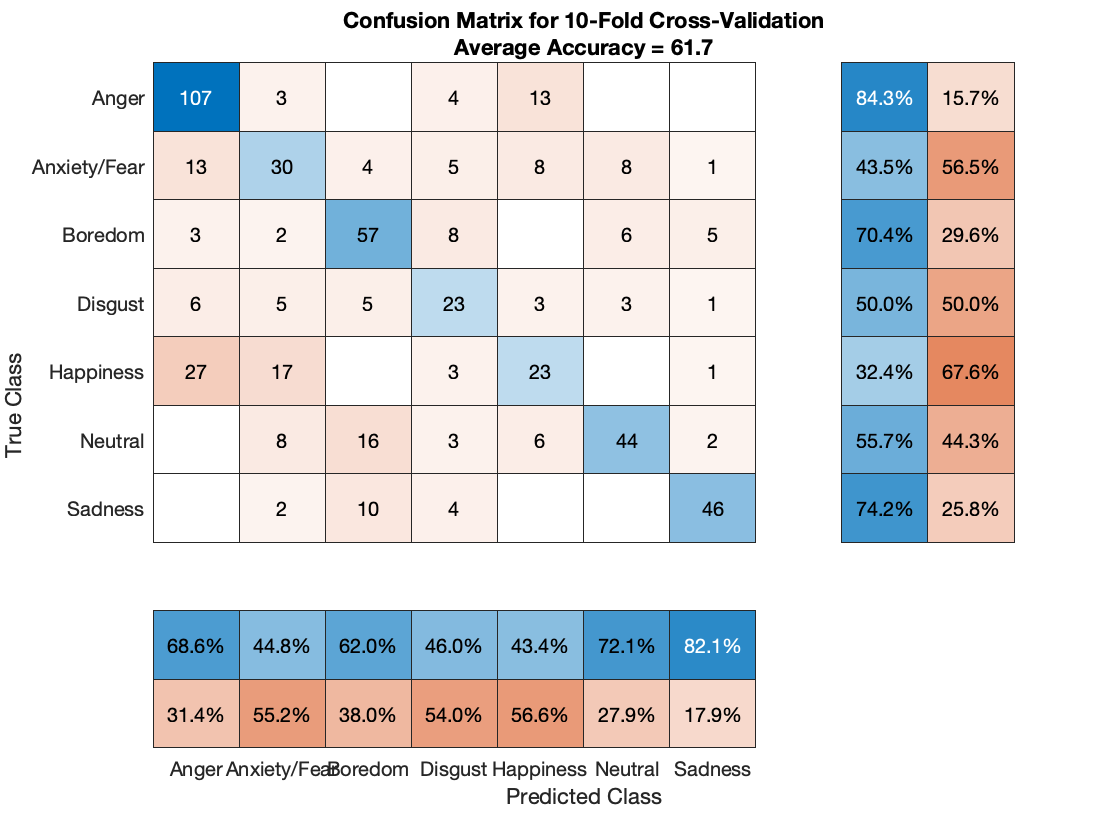


labelsTrueMat = cat(1,labelsTrue{:});
labelsPredMat = cat(1,labelsPred{:});
figure
cm = confusionchart(labelsTrueMat,labelsPredMat);
valAccuracy = mean(labelsTrueMat==labelsPredMat)*100;
cm.Title = sprintf('Confusion Matrix for 10-Fold Cross-Validation\nAverage Accuracy = %0.1f',valAccuracy);
%sortClasses(cm,categories(emptyEmotions))
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';


% % 9. Evaluate the network. Call classify to get the predicted labels
% % for each sequence. Get the mode of the predicted labels of each
% % sequence to get the predicted labels of each file.
% predictedLabelsPerSequence = classify(net,sequencesValidation);
% trueLabels = categorical(adsValidation.Labels);
% predictedLabels = trueLabels;
% idx1 = 1;
% for ii = 1:numel(trueLabels)
%     predictedLabels(ii,:) = mode(predictedLabelsPerSequence(idx1:idx1 + sequencePerFileValidation{ii} - 1,:),1);
%     idx1 = idx1 + sequencePerFileValidation{ii};
% end
% trueLabelsCrossFold{i} = trueLabels; %#ok<AGROW>
% predictedLabelsCrossFold{i} = predictedLabels; %#ok<AGROW>

## Supporting Functions

function [predictor,response,segmentsPerFile] = vggishPreprocess(ads,overlap)
% This function is for example purposes only and may be changed or removed
% in a future release.
%extractor = afe;
% Create filter bank
% FFTLength = 512;
numBands = 64;
% fs0 = 16e3;
% filterBank = designAuditoryFilterBank(fs0, ...
%     'FrequencyScale','mel', ...
%     'FFTLength',FFTLength, ...
%     'FrequencyRange',[125 7500], ...
%     'NumBands',numBands, ...
%     'Normalization','none', ...
%     'FilterBankDesignDomain','warped');
% 
% % Define STFT parameters
% windowLength = 0.025 * fs0;
% hopLength = 0.01 * fs0;
% win = hann(windowLength,'periodic');

% Define spectrogram segmentation parameters
segmentDuration = 0.96; % seconds
segmentRate = 100; % hertz
segmentLength = segmentDuration*segmentRate; % Number of spectrums per auditory spectrograms
segmentHopDuration = (100-overlap) * segmentDuration / 100; % Duration (s) advanced between auditory spectrograms
segmentHopLength = round(segmentHopDuration * segmentRate); % Number of spectrums advanced between auditory spectrograms

% Preallocate cell arrays for the predictors and responses
numFiles = numel(ads.Files);
predictor = cell(numFiles,1);
response = predictor;
segmentsPerFile = zeros(numFiles,1);

% Extract predictors and responses for each file
for ii = 1:numFiles
    [audioIn,info] = read(ads);
%     featureVector = cellfun(@(audioIn)extract(extractor,audioIn),audioIn,"UniformOutput",false);
    x=audioIn;
    fs=16000;
    [f0,~] = pitch(x,fs,'Method','LHS','WindowLength',640,'OverlapLength',480);
    [fMIDI_V]=fo_embedding_interval_test(f0);

    [musicV2]=music_rep_emb_test(x,fs);
    [musicV2_melody]=music_rep_emb_melody_test(x,fs);
    [musicV2_Interval]=music_rep_emb_interval_test(musicV2,musicV2_melody);
    featureVector=[musicV2_Interval fMIDI_V];
%     x = single(resample(audioIn,fs0,info.SampleRate));
% 
%     Y = stft(x, ...
%         'Window',win, ...
%         'OverlapLength',windowLength-hopLength, ...
%         'FFTLength',FFTLength, ...
%         'FrequencyRange','onesided');
%     Y = abs(Y);
    Y=featureVector';
    logMelSpectrogram = Y';
    
    % Segment log-mel spectrogram
    if size(Y,2)<96
        Y=[Y zeros(size(Y,1),96-size(Y,2))];
        logMelSpectrogram = Y';
    end
    
    numHops = floor((size(Y,2)-segmentLength)/segmentHopLength) + 1;
    segmentedLogMelSpectrogram = zeros(segmentLength,numBands,1,numHops);
    for hop = 1:numHops
        segmentedLogMelSpectrogram(:,:,1,hop) = logMelSpectrogram(1+segmentHopLength*(hop-1):segmentLength+segmentHopLength*(hop-1),:);
    end

    predictor{ii} = segmentedLogMelSpectrogram;
    response{ii} = repelem(info.Label,numHops);
    segmentsPerFile(ii) = numHops;
end

% Concatenate predictors and responses into arrays
predictor = cat(4,predictor{:});
response = cat(2,response{:});
end

*Copyright 2020 The MathWorks, Inc.*